# underscore 2018

## Q 4

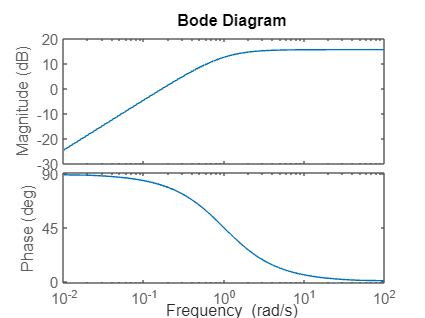

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,10000);
s = tf('s');

numG = 6*s;                        % numerator
denG = s+1; % denominator

G = numG/denG;
bode(G)

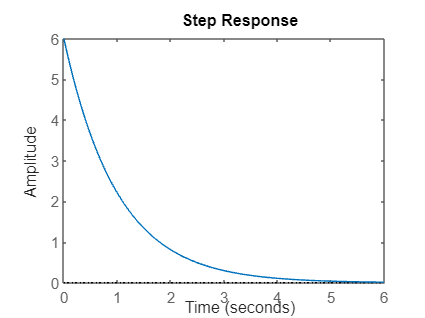

step(G)

## Q5

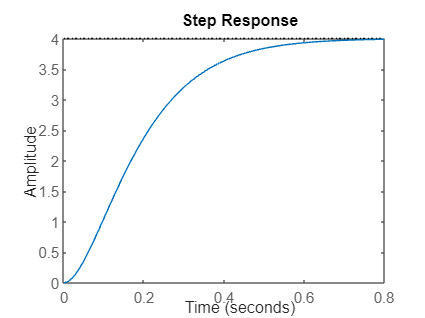

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,10000);
s = tf('s');

numG = 400;                        % numerator
denG = (s^2+20*s+100); % denominator

G = numG/denG;
step(G)

## Q6

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,10000);
s = tf('s');

numG = 400;                        % numerator
denG = (s^2+20*s+100); % denominator

G = numG/denG;

t=0.5-0.1



## Q10

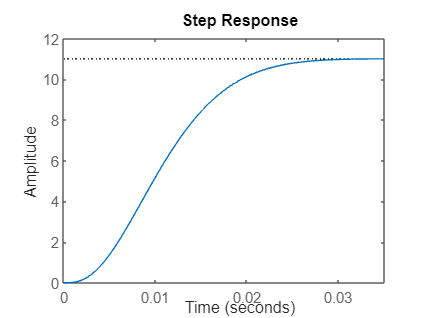

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,10000);
s = tf('s');

numG = 687500;                        % numerator
denG = (s^2+400*s+62500)*(0.0048*s+1); % denominator

G = numG/denG;
step(G)


mag=db2mag(21)

mag = 11.2202

dcgain(G)

ans = 11


gp=pole(G)

gp = 1.0e+02 *

  -2.0000 + 1.5000i
  -2.0000 - 1.5000i
  -2.0833 + 0.0000i


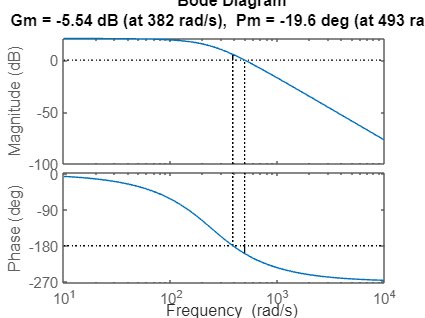

%bode(G)
margin(G)

% hvis vi har stable i open loop så har vi også i closed. Men vi har ikke i
% closed


## Q11



K = 1/0.5

K = 2

mag2db(K)

ans = 6.0206

## Q12

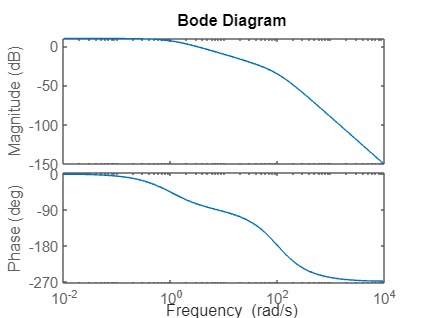

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,10000);
s = tf('s');

numG = 30000;                        % numerator
denG = s^3+181*s^2+10180*s+10000; % denominator

G = numG/denG;
bode(G)

w = linspace(1e-4,120,10000);

[mag,phase] = bode(G,w);
mag = squeeze(mag);
phase = squeeze(phase);
ym = -120;
p_c =find(phase < ym,1,'first');
wc=w(p_c);

Kp= abs(freqresp(G,wc))

Kp = 0.0905

K=1/Kp

K = 11.0441

## Q13

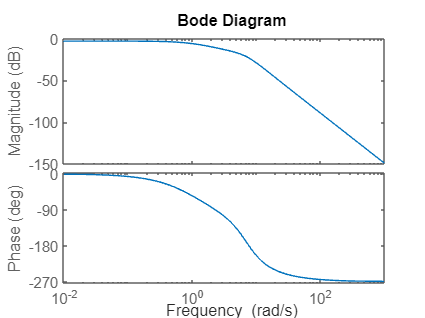

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000);
s = tf('s');

numG = 0.7;                        % numerator
denG = 0.0196*s^3+0.1876*s^2+1.168*s+1; % denominator

G = numG/denG;
bode(G)

[mag,phase] = bode(G,w);
mag = squeeze(mag);
phase = squeeze(phase);

% vairabler
ym=60;
Ni=2;

% Phase bidrag
phCi = atand(-1/Ni);
Gphas = -180 + ym - phCi;




p_c =find(phase > Gphas,1,'last');
wc=w(p_c);
tau_i = Ni*(1/wc)

tau_i = 0.8325


% I kontroller uden KP
Ci = ((tau_i*s+1)/(tau_i*s));

Kp = 1/(abs(freqresp(Ci*G,wc)))

Kp = 3.2400

## Q14

clf;
clear all;
clc;

Ni=2.5;
a=0.15

a = 0.1500

ym=50;
phCi = atand(-1/Ni);
phCm = asind((1-a)/(1+a));
Gphas=-180+ym-phCi-phCm

Gphas = -155.8560

wc=0.6;



## Q16

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000);
s = tf('s');

numG = 0.7;                        % numerator
denG = 0.0196*s^3+0.1876*s^2+1.168*s+1; % denominator

G = numG/denG;
bode(G)